# Trim, Linearise and design an **OBSERVER** for the quadcopter and **PENDULUM** model:

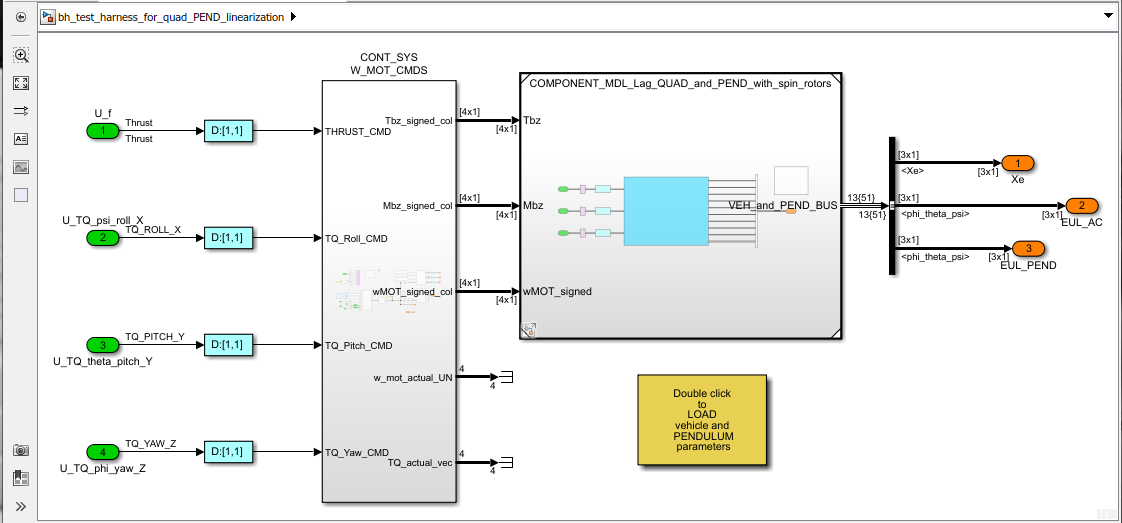

In this task we're going to linearise our **Simulink** quadcopter model. We're going to do this because we'd like to apply some "state space" control design techniques in order to design a control system for the quadcopter.  And as you know, these control techniques require a LINEAR plant model.  The workflow that we'll follow is this:

- We'll find an operating point for the pendulum. An operating point is characterized by the state(X), the input(U) and the output(Y).    We'll look specifically for an operating point that corresponds to steady state, ie: where the pendulum's state derivatives are ZERO. This is referred to as finding a **TRIMMED operating point**.

- We'll then use this TRIMMED operating point to calculate a **linearised** version of the quadcopter model.

- Finally, we'll then use this linearised model to design a full state feedback control system using the Linear Quadratic Integrator (LQI) technique.

`Bradley Horton : 08-Oct-2017, bradley.horton@mathworks.com.au`

# 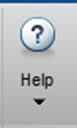 Take a moment !

If you're interested in reading about how to linearize a NON linear plant model.  Use the MATLAB HELP browser and try this simple text search

- `linearize control system`

HINT:  today we'll be using the functions:

- `operspec,   findop,   linearize`

## Load the model parameters:

bh_quad_params
bh_pend_params
bh_create_veh_and_pend_BUS

Just ensure that the the initial local Euler angles of the pendulum are ZERO:

P_pend.eul_loc_vec      = [0,0,0]'; % rad
P_veh_no_props.eul_init = [0,0,0]'; % rad

ANd echo the parameters that have been loaded into the workspace:

whos

  Name                   Size            Bytes  Class           Attributes

  PEND_BUS               1x1               311  Simulink.Bus              
  P_elec                 1x1               352  struct                    
  P_mot                  1x1              1232  struct                    
  P_mot_alone            1x1              1232  struct                    
  P_mot_vec              4x1              3584  struct                    
  P_one_prop             1x1               880  struct                    
  P_pend                 1x1               992  struct                    
  P_rot                  1x1               592  struct                    
  P_veh                  1x1              1536  struct                    
  P_veh_no_props         1x1              1536  struct                    
  VEH_AND_PEND_BUS       1x1               703  Simulink.Bus              
  XYZ_circ_mat          88x3              2112  double                    
  X_TS_OBJ              

warning('off')

## The name of the SIMULINK model that we'll linearise:

model  = 'bh_test_harness_for_quad_PEND_linearization';
set_param(0, 'CallbackTracing', 'off')
open_system(model)

## Create the operating point specification object.

opspec = operspec(model);

In our operating point specification, note the following:

- Our GREEN root level INPORT blocks are the system inputs 

- Our ORANGE root level OUTPORT blocks are the system outputs 

display(opspec)

opspec =  Operating point specification for the Model bh_test_harness_for_quad_PEND_linearization.
 (Time-Varying Components Evaluated at time t=0)

States: 
----------
    x    Known    SteadyState    Min     Max    dxMin    dxMax
    _    _____    ___________    ____    ___    _____    _____

(1.) DOT_phi
    0    false       true        -Inf    Inf    -Inf      Inf 
(2.) 

For each of our model states we can specify "desired" values for each of the following.  

- `x           :`   initial guess for state value

- `SteadyState :`   a logical indicating we are looking for a dx=0 final value

- `Min         :`   minimum bound for state value

- `Max         :`   maximum bound for state value

For our problem, we're going to look for an operating point where ALL of our states are at SteadyState (ie: dx/dt=0)

%[ opspec.States(1).SteadyState]
%[ arrayfun(@(a) (a.SteadyState), opspec.States) ].'

Our trimming function(coming up next) will then look for an operating point that satisfies this specification:

## Look for the steady state operating point.

opt           = findopOptions('DisplayReport','off');
[op,opreport] = findop(model,opspec, opt);

Review our trimmed OPERATING point and NOTE the following:

- We have indeed found a steady state operating point because the state derivatives are either zero OR very small $O(10^{-7})$

- In this trimmed pose, ALL of the system outputs are ZERO.

- To maintain this trimmed pose we need to supply an INPUT force ... which is the force to counter gravity. 

display(opreport)

opreport =  Operating point search report for the Model bh_test_harness_for_quad_PEND_linearization.
 (Time-Varying Components Evaluated at time t=0)

Operating point specifications were successfully met.
States: 
----------
    Min          x         Max    dxMin        dx         dxMax
    ____    ___________    ___    _____    ___________    _____

(1.) DOT_phi
    -Inf              0    Inf      0      -7.8458e-29      0  
(2.) 

## Linearize the model about this operating point:

Next we'll linearise our model about this trimmed operating point:

my_LIN_PLANT = linearize(model,op);

What are the size attributes of the linearized model ?

size(my_LIN_PLANT)

State-space model with 9 outputs, 4 inputs, and 18 states.


Note the names of the **INPUTS** "U"  

my_LIN_PLANT.InputName

ans = 4×1 cell array
    {'U_f'               }
    {'U_TQ_psi_roll_X'   }
    {'U_TQ_theta_pitch_Y'}
    {'U_TQ_phi_yaw_Z'    }


and the **OUTPUTS** "Y" 

my_LIN_PLANT.OutputName(1:3) = {'Xe','Ye','Ze'};
my_LIN_PLANT.OutputName

ans = 9×1 cell array
    {'Xe'           }
    {'Ye'           }
    {'Ze'           }
    {'EUL_AC(1,1)'  }
    {'EUL_AC(2,1)'  }
    {'EUL_AC(3,1)'  }
    {'EUL_PEND(1,1)'}
    {'EUL_PEND(2,1)'}
    {'EUL_PEND(3,1)'}


and the **STATES** "X"

my_LIN_PLANT.StateName

ans = 18×1 cell array
    {'DOT_phi'       }
    {'DOT_theta'     }
    {'DOT_psi'       }
    {'DOT_Xe'        }
    {'DOT_Ye'        }
    {'DOT_Ze'        }
    {'DOT_phi_pend'  }
    {'DOT_theta_pend'}
    {'DOT_psi_pend'  }
    {'phi'           }
    {'theta'         }
    {'psi'           }
    {'Xe'            }
    {'Ye'            }
    {'Ze'            }
    {'phi_pend'      }
    {'theta_pend'    }
    {'psi_pend'      }


Check if the linearised system is Full state Feedback(FSFB) **Controllable**. If the system is NOT FSFB controllable it means that we can NOT ***arbitrarily position*** the system poles.  We may still be able to position them to obtain a stable system  ... it's just that we can't arbitrarily position them.

co = ctrb(my_LIN_PLANT);
if(rank(co) ~= size(my_LIN_PLANT.A,1) )
    fprintf('###_ATTENTION: the LINEARISED system is NOT FSFB controllable');
    ["Rank(co)="+rank(co)+"  size(A,1)="+size(my_LIN_PLANT.A,1)]
else
    fprintf(" ----->  YES.  System is CONTROLLABLE");
    ["Rank(co)="+rank(co)+"  size(A,1)="+size(my_LIN_PLANT.A,1)]
end

###_ATTENTION: the LINEARISED system is NOT FSFB controllable

ans = "Rank(co)=14  size(A,1)=18"

What about the **Observability** of the system:

ob = obsv(my_LIN_PLANT);
if(rank(ob) ~= size(my_LIN_PLANT.A,1) )
    fprintf('###_ATTENTION: the LINEARISED system is NOT observable');
    ["Rank(ob)="+rank(ob)+"  size(A,1)="+size(my_LIN_PLANT.A,1)]
else
    fprintf(" ----->  YES.  LINEARISED System is OBSERVABLE");
    ["Rank(ob)="+rank(ob)+"  size(A,1)="+size(my_LIN_PLANT.A,1)]
end

 ----->  YES.  LINEARISED System is OBSERVABLE

ans = "Rank(ob)=18  size(A,1)=18"

And close the model:

close_system(model)
set_param(0, 'CallbackTracing', 'on')

## OK, explore reducing the system

First recall the current SIZE of the linearised model:

size(my_LIN_PLANT)

State-space model with 9 outputs, 4 inputs, and 18 states.


Now use [`minreal()`](matlab:  web(fullfile(docroot, 'control/ref/lti.minreal.html'))) to eliminate some of the uncotrollable states.

my_plant = minreal(my_LIN_PLANT);

2 states removed.


And the size of our reduced system is:

size(my_plant)

State-space model with 9 outputs, 4 inputs, and 16 states.


%my_plant.C

What about **FSFB Controllability**

co = ctrb(my_plant);
if(rank(co) ~= size(my_plant.A,1) )
    fprintf('###_ATTENTION: the Reduced system is NOT FSFB controllable');
    ["Rank(co)="+rank(co)+"  size(A,1)="+size(my_plant.A,1)]
else
    fprintf(" ----->  YES.  Reduced System is CONTROLLABLE");
    ["Rank(co)="+rank(co)+"  size(A,1)="+size(my_plant.A,1)]
end

###_ATTENTION: the Reduced system is NOT FSFB controllable

ans = "Rank(co)=14  size(A,1)=16"

What about the **Observability** of the system:

ob = obsv(my_plant);
if(rank(ob) ~= size(my_plant.A,1) )
    fprintf('###_ATTENTION: the Reduced system is NOT observable');
    ["Rank(ob)="+rank(ob)+"  size(A,1)="+size(my_plant.A,1)]
else
    fprintf(" ----->  YES.  Reduced System is OBSERVABLE");
    ["Rank(ob)="+rank(ob)+"  size(A,1)="+size(my_plant.A,1)]
end

 ----->  YES.  Reduced System is OBSERVABLE

ans = "Rank(ob)=16  size(A,1)=16"

## OK, design an observer for the REDUCED plant

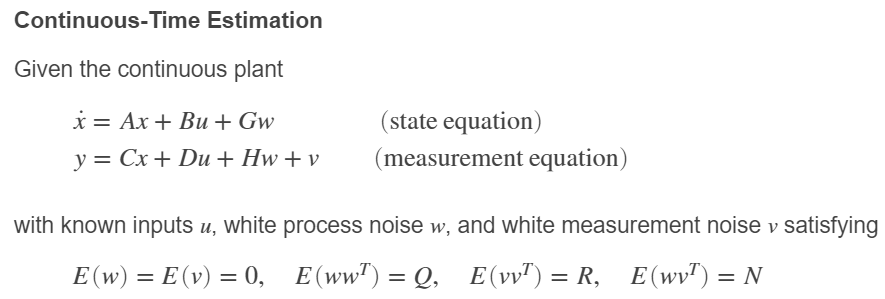

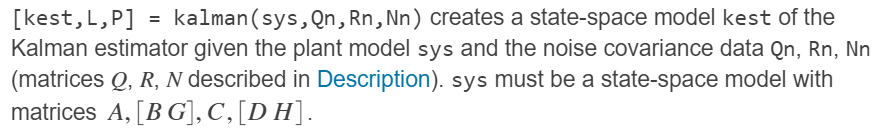

### OBSERVER design #1:

- 
$$G\;=I_{N_X \times N_X }$$


- 
$$H\;=0_{N_Y \times N_X }$$
 

[Nx,Ny,Nu]      = deal(size(my_plant.A,1), size(my_plant.C,1), size(my_plant.B,2));

tmp_G_mat       = diag(   ones( size(my_plant.A,1), 1 )   );        
tmp_H_mat       = zeros(  size(my_plant.D,1),  size(tmp_G_mat,2)  );

new_input_names = [         string(my_plant.InputName); ...
                    ("w_" + string(my_plant.StateName))  ];            
new_input_names = cellstr(new_input_names);  

the_sys         = ss( my_plant.A,   [my_plant.B, tmp_G_mat], ...
                      my_plant.C,   [my_plant.D, tmp_H_mat], 'inputname', new_input_names);

Qobs = 5e4  * diag(ones(1,size(tmp_G_mat,2)));
Robs = 1e-1    * diag(ones(1,Ny));

[kest_1,~,~] = kalman(the_sys,Qobs,Robs,[]);

size(kest_1)

State-space model with 25 outputs, 13 inputs, and 16 states.


### OBSERVER design #2:

- $G\;=B$      where   $B\;\in \;R^{N_X \times N_U }$

- $H\;=D$    where   $D\;\in \;R^{N_Y \times N_U }$

tmp_G_mat       = my_plant.B;        
tmp_H_mat       = my_plant.D;

new_input_names = [         string(my_plant.InputName); ...
                    ("w_" + string(my_plant.InputName))  ];
             
new_input_names = cellstr(new_input_names);  
        
the_sys = ss( my_plant.A, [my_plant.B, tmp_G_mat], ...
              my_plant.C, [my_plant.D, tmp_H_mat], 'inputname', new_input_names);

[Nx,Ny,Nu] = deal(size(my_plant.A,1), size(my_plant.C,1), size(my_plant.B,2));

Qobs = 1e4    * diag(ones(1,Nu));
Robs = 1 * diag(ones(1,Ny));

%[the_sys, Qn, Rn] = LOC_plant_for_KAL_design(my_plant);
[kest_2,~,~] = kalman(the_sys,Qobs,Robs,[]);

size(kest_2)

State-space model with 25 outputs, 13 inputs, and 16 states.


## Open a Simulink model to assess OBSERVER behaviour

Which Observer do you want to play with ?

kest = kest_2;   %  kest_1;

How well does the OBSERVER estimate the measureable outputs ?

bh_create_local_params_QP_and_CONTROL_LAW


--------------------------------------------------
 ATTENTION:  (from bh_create_local_params_QP_and_CONTROL_LAW)

     Have just loaded Control Law into Workspace
--------------------------------------------------
###
##
#




open_system("bh_SM_quad_and_PEND.slx")

# Local Subfunctions ONLY beyond this point

Generic:

- 
$$\begin{array}{l}
\dot{x} =A\ldotp x\;\;\;+\;\;\;B\ldotp u\;\;\;+\;\;G\ldotp w\\
y=C\ldotp x\;\;\;+\;\;D\ldotp u\;\;\;+\;\;H\ldotp w\;\;+\;\;v
\end{array}$$


My case:

- 
$$\begin{array}{l}
\dot{x} =A\ldotp x\;\;+\;\;B\ldotp \left(u\;+\;w\right)\\
y=C\ldotp x\;\;+\;D\ldotp \left(u+w\right)+\;\;v
\end{array}$$


%  function [the_sys, Qn, Rn] = LOC_plant_for_KAL_design(my_plant)
%      
%      new_input_names = [         string(my_plant.InputName); ...
%                          ("w_" + string(my_plant.InputName))  ];
%      new_input_names = cellstr(new_input_names);                
%     %  new_output_names = [         string(my_plant.OutputName), ...
%     %                      ("w_" + string(my_plant.OutputName))  ];                 
%     
%     the_sys = ss(my_plant.A, [my_plant.B, my_plant.B], ...
%                               my_plant.C, ...
%                              [my_plant.D,my_plant.D], 'inputname', new_input_names);
%     
%     [Nx,Ny,Nu] = deal(size(my_plant.A,1), size(my_plant.C,1), size(my_plant.B,2));
%     
%      Qn = 1*diag(ones(1,Nu));
%      Rn = 1*diag(ones(1,Ny));
%   
%  end